clear;
if exist('DataSet','dir')
   rmdir('.\DataSet\', 's');
end

mkdir('.\DataSet\');

% 配置
global run_type;
run_type = 'io';
config;

L_recTre = 129.0309


% 产生信号
source;
tag;
global y_sig;
y_sig = y_source;

% % dB 单位信噪比
% y_noise = awgn(y_sig, 50);
% y_sig = y_noise;

global Length;
global Width;

## 房间内的随机点(测试集)

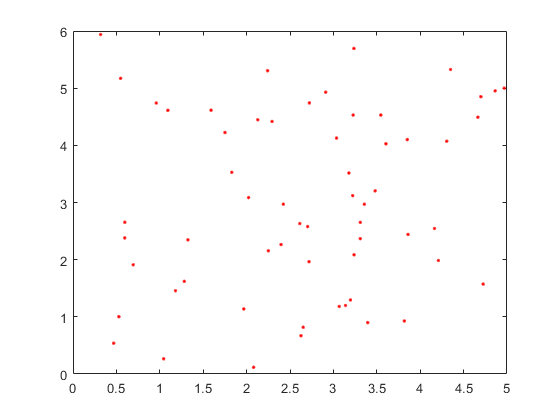

N_inside = 60;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1, d2, d3] = xy2d(x, y,j, 'inside');
    single_run(d1, d2, d3, false, 'inside', j);
end

L_tag is
  列 1 至 14

  103.0766  106.3975  106.5539  107.4341  106.2657  110.6897   99.9300  107.4403  100.7943  100.5526  105.8735  103.8140  103.6059  106.7061

  列 15 至 28

  108.1963  102.0253  106.6724  103.8736  109.2205  108.9889  101.1558  106.3272  105.6322  105.0222  110.0806  101.5994  101.2404  100.4616

  列 29 至 42

  110.7281  106.5008  104.2096  106.6586  104.9796  107.1418  105.1187  107.4961  104.7719  111.4835   99.6644   98.8600   96.6614   94.1130

  列 43 至 56

  103.1951  103.4355  102.5974  108.6117  106.5326  108.1927  110.4876  111.1970   99.0407  100.2469  107.1052   98.2197  105.2426  105.2344

  列 57 至 60

  109.4226  104.2433  102.9565  106.7755

delta t is
   1.0e-07 *

  列 1 至 14

    0.0590    0.0995    0.1042    0.1281    0.0983    0.1866    0.0490    0.1247    0.0317    0.0139    0.0954    0.0606    0.0654    0.1057

  列 15 至 28

    0.1355    0.0429    0.1044    0.0886    0.1543    0.1481    0.0327    0.1073    0.0998    0.0769    0.1799    0.0290    0

Rate_miss = 0

L_tag is
  列 1 至 14

  103.1682  106.4335  106.5801  107.4523  106.3068  110.7060   99.9501  107.4855  100.8250  100.6096  105.9254  103.8480  103.6886  106.7341

  列 15 至 28

  108.2327  102.1266  106.7029  103.8912  109.2406  109.0121  101.1882  106.3481  105.6999  105.0575  110.1153  101.6435  101.3769  100.5109

  列 29 至 42

  110.7570  106.5534  104.2438  106.6797  105.0517  107.2038  105.1473  107.5358  104.8088  111.5099   99.8491   98.8868   97.0882   95.0464

  列 43 至 56

  103.2477  103.5485  102.6662  108.6286  106.5533  108.2173  110.5158  111.2243   99.2612  100.2859  107.1390   98.2423  105.2620  105.2545

  列 57 至 60

  109.4529  104.2875  102.9812  106.8085

delta t is
   1.0e-07 *

  列 1 至 14

    0.0599    0.1001    0.1048    0.1286    0.0989    0.1870    0.0494    0.1254    0.0322    0.0147    0.0961    0.0612    0.0663    0.1062

  列 15 至 28

    0.1361    0.0439    0.1050    0.0890    0.1547    0.1486    0.0333    0.1078    0.1006    0.0775    0.1805    0.0297    0

Rate_miss = 0

## 房间周围的随机点

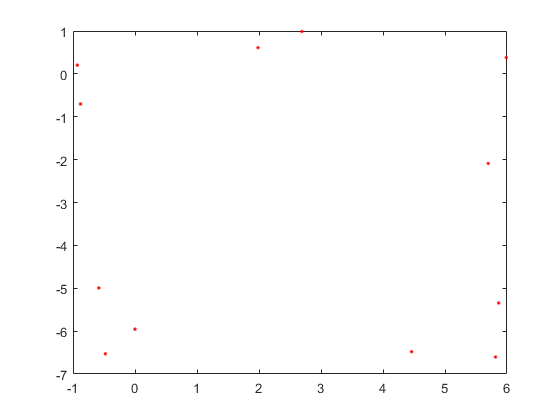

% 1/4 的数量
N_outside = 3;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
figure; plot(x0,y0,'r.');


% 计算三个距离
for j=1:2
    [d1_0, d2_0, d3_0] = xy2d(x0, y0, j, 'outside');
    SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside', j);
end

  160.9807  120.1334  119.3935
  168.2912  227.5010  178.1437
  116.9586  117.3079  113.3965
  166.8874  176.5885  230.9424

delta t is
   1.0e-07 *

    0.1103    0.0611    0.0349
    0.1533    0.2363    0.2952
    0.0547    0.0169    0.0260
    0.2153    0.2908    0.2642

  161.0095  120.1508  119.4171
  168.3156  227.5297  178.1617
  117.5644  117.6560  114.4801
  166.9209  176.6084  230.9816

delta t is
   1.0e-07 *

    0.1107    0.0615    0.0354
    0.1537    0.2367    0.2955
    0.0572    0.0188    0.0293
    0.2159    0.2913    0.2646



## 上下房间

N_up = 10;
x_u = Width * rand(1, N_up);
y_u = Length * rand(1, N_up);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_u, d2_u, d3_u] = xy2d(x, y,j, 'up');
    single_run(d1_u, d2_u, d3_u, false, 'up', j);
end

L_tag is
  列 1 至 14

  123.0966  126.2240  126.2631  127.0529  126.1332  130.5125  117.1309  127.3951  119.5794  120.0192  125.8042  123.3686  123.6064  126.4558

  列 15 至 28

  128.1200  122.0355  126.4537  122.8299  129.0227  128.8216  120.1374  125.8969  125.6457  124.7346  130.0566  121.0197  121.3734  119.7700

  列 29 至 42

  130.6842  126.4641  123.8180  126.2704  124.9889  127.1792  124.7274  127.4144  124.4830  131.4427  119.9082  116.2519  117.5377  116.1455

  列 43 至 56

  122.9446  123.5705  122.4415  128.3089  126.1213  127.9978  130.4311  131.1553  119.3842  119.2153  126.9522  113.9294  124.6035  124.6256

  列 57 至 60

  129.3468  123.9979  122.0812  126.5935

delta t is
   1.0e-07 *

  列 1 至 14

    0.0572    0.0964    0.1001    0.1233    0.0955    0.1834    0.0348    0.1228    0.0228    0.0084    0.0932    0.0555    0.0635    0.1019

  列 15 至 28

    0.1333    0.0410    0.1009    0.0802    0.1509    0.1451    0.0247    0.1022    0.0983    0.0729    0.1784    0.0232    0

Rate_miss = 0.1167

L_tag is
  列 1 至 14

  122.9914  126.1819  126.2322  127.0315  126.0852  130.4932  117.1072  127.3424  119.5434  119.9530  125.7437  123.3288  123.5112  126.4229

  列 15 至 28

  128.0773  121.9197  126.4179  122.8092  128.9990  128.7943  120.0994  125.8723  125.5673  124.6932  130.0159  120.9681  121.2192  119.7125

  列 29 至 42

  130.6502  126.4029  123.7780  126.2456  124.9056  127.1073  124.6938  127.3680  124.4397  131.4116  119.7031  116.2204  117.1011  115.3259

  列 43 至 56

  122.8834  123.4418  122.3619  128.2889  126.0969  127.9688  130.3980  131.1231  119.1425  119.1698  126.9126  113.9027  124.5807  124.6019

  列 57 至 60

  129.3112  123.9462  122.0522  126.5548

delta t is
   1.0e-07 *

  列 1 至 14

    0.0561    0.0957    0.0995    0.1228    0.0948    0.1829    0.0343    0.1220    0.0221    0.0075    0.0923    0.0548    0.0625    0.1013

  列 15 至 28

    0.1326    0.0398    0.1002    0.0797    0.1503    0.1445    0.0240    0.1017    0.0973    0.0722    0.1777    0.0224    0

Rate_miss = 0.1167


N_dn = 10;
x_d = Width * rand(1, N_dn);
y_d = Length * rand(1, N_dn);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_d, d2_d, d3_d] = xy2d(x, y,j, 'down');
    single_run(d1_d, d2_d, d3_d, false, 'down', j);
end

L_tag is
  列 1 至 14

  129.6891  131.1641  131.3730  132.1501  131.0928  133.9982  129.8484  131.8783  129.1105  128.3389  130.9405  129.9346  129.9035  131.4104

  列 15 至 28

  132.2789  129.1739  131.3545  130.9412  132.9893  132.7846  129.1105  131.4908  131.0019  130.4448  133.5900  128.8781  129.0902  128.4087

  列 29 至 42

  133.9712  131.3530  130.0942  131.6264  130.6338  131.9617  130.6344  131.8487  130.3042  134.4978  128.6244  129.0065  128.5131  128.9865

  列 43 至 56

  129.4589  130.2071  129.2055  132.7978  131.5901  132.2905  133.7847  134.2971  128.5642  128.6084  131.5788  129.3282  131.1803  131.1129

  列 57 至 60

  133.0541  129.9905  130.0430  131.3904

delta t is
   1.0e-07 *

  列 1 至 14

    0.1679    0.1948    0.1998    0.2213    0.1939    0.2658    0.1753    0.2154    0.1532    0.1350    0.1925    0.1679    0.1720    0.2003

  列 15 至 28

    0.2232    0.1563    0.1989    0.1985    0.2389    0.2333    0.1525    0.2049    0.1980    0.1784    0.2603    0.1458    0

Rate_miss = 0.8500

L_tag is
  列 1 至 14

  129.8435  131.2638  131.4550  132.2136  131.2003  134.0568  129.9166  131.9914  129.2010  128.4659  131.0619  130.0309  130.0522  131.4959

  列 15 至 28

  132.3793  129.3336  131.4447  131.0030  133.0576  132.8601  129.2042  131.5609  131.1390  130.5435  133.6876  128.9899  129.2649  128.5270

  列 29 至 42

  134.0584  131.4752  130.1909  131.6970  130.7746  132.0937  130.7210  131.9541  130.4054  134.5800  128.8124  129.0896  128.7271  129.2134

  列 43 至 56

  129.5811  130.3726  129.3436  132.8581  131.6598  132.3691  133.8705  134.3813  128.7589  128.7127  131.6748  129.4024  131.2466  131.1812

  列 57 至 60

  133.1440  130.1024  130.1217  131.4850

delta t is
   1.0e-07 *

  列 1 至 14

    0.1706    0.1970    0.2018    0.2231    0.1962    0.2675    0.1771    0.2177    0.1553    0.1375    0.1950    0.1700    0.1747    0.2023

  列 15 至 28

    0.2254    0.1591    0.2010    0.2003    0.2407    0.2352    0.1546    0.2068    0.2006    0.1806    0.2625    0.1482    0

Rate_miss = 0.8833

% 画出散点
figure; plot(x_u,y_u,'r.');
figure; plot(x_d,y_d,'r.');

## 保存数据集的信息

% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'N_up', 'N_dn',...
    'x', 'y', 'd1', 'd2', 'd3', ...
    'x0', 'y0', 'd1_0', 'd2_0', 'd3_0', ...
    'x_u', 'y_u', 'd1_u', 'd2_u', 'd3_u', ...
    'x_d', 'y_d', 'd1_d', 'd2_d', 'd3_d');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end

% up
for i=1: N_up
    preproc('u_sig_rx', i, false, 'up');
end

% down
for i=1: N_dn
    preproc('d_sig_rx', i, false, 'down');
end